# **Breast Cancer: Patient survival prediction.**

**A cancer patient data set containing 314 patient samples and approx 22k genes or features will be used to train a model to predict patient survival into three possible classes: alive, alive_relapse, relapse_dead.**

%load Data
load('cnv_smote.mat');
load('mirna_smote.mat');
load('rna_smote.mat');
load('protein_smote.mat');
load('mutation_smote.mat');
load('meth_smote.mat');

load('clinical_smote.mat');
response= readtable('response.xlsx');

cnv = (table2array(cnv))';
rna = (table2array(rna))';
mirna = (table2array(mirna))';
protein = (table2array(protein))';
mutation = (table2array(mutation))';
methylation = (table2array(methylation))';
clinical = (table2array(clinical))';
t = (table2array(response))';

x= {cnv; mirna; rna; protein; mutation; clinical; methylation};

rng(1);
k=10;
cvnn = cvpartition(t,'KFold',k)

cvnn = K-fold cross validation partition
   NumObservations: 532
       NumTestSets: 10
         TrainSize: 479  478  478  479  479  479  479  479  479  479
          TestSize: 53  54  54  53  53  53  53  53  53  53

hiddenLayerSize = [7 7];
%net = feedforwardnet(T.hiddenLayerSize, 'trainscg');
net = feedforwardnet(hiddenLayerSize, 'trainscg');
net.trainParam.lr =0.5411;
%net.performParam.regularization = 0.999983155175642;
%net.performParam.regularization = 0.99998;
%net.trainParam.lr =T.lr;
net.performParam.regularization =0.9999;
net.trainParam.lr

ans = 0.5411

net.performParam.regularization

ans = 0.9999

ans =    128   112   182   188   258   209   494   416   409   101   393    18   344   368   476   429   483   473   512   359    88   330   499   487   325    62   277   365   333   501   323   525   169   430   414   391   453    76   184    69    23   504   402   446   207    82   328    80   397    20


ans =    189   497   145   423    30    63   181   511   167   296   492   175   319   245   199   232   114   304   102   190   100   503   448   526   495   454   373   285   438   154   135   387   246   355   468   436   197   130   520   249    70   161   358    26   428   252    32   322   196   113


ans =     19    35    45    49    51    53    59    66    67    85    87    95   103   104   107   115   117   126   140   147   163   168   170   186   218   229   250   254   266   272   286   289   290   300   312   331   342   360   366   375   385   410   424   425   426   447   462   474   478   505


performance = 0.7577

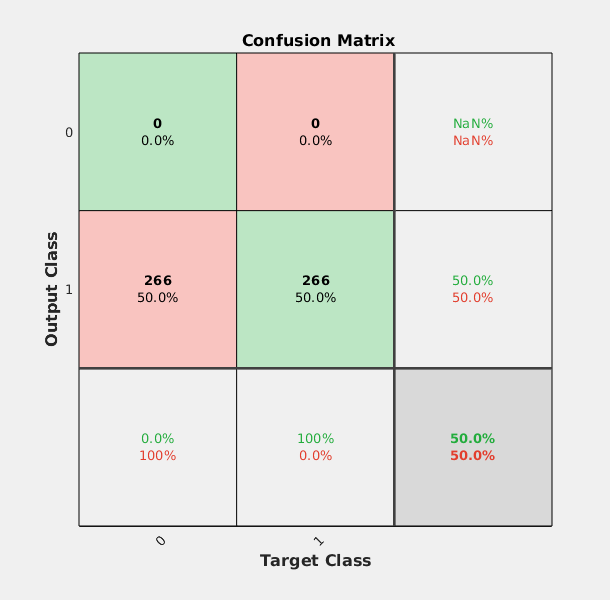

ans =    513    12   524   128   252   467   155    31   411   364   118   182   291   448   206    47   366   248   414   245   419   285   108     8   351   158   253   424   307   520   320   280    56    37    62     1    44   317   463   422   353   126   333   488   525   323   355   159   496   220


ans =    500   149   157   492    71   140   506   167   295   165    18   119   139   265   329   257   412    75   260   187   516   338   425   382   501   256   360   134   229   381    38   388   531   327   396   146   208   172   395    28   148   497   136   345    52   239    14   115   214   321


ans =      3    10    24    26    58    90    98   101   121   151   177   179   180   193   198   200   210   235   240   242   244   262   263   270   274   275   284   309   314   319   325   337   346   347   348   357   367   397   398   400   405   417   418   423   445   449   451   461   471   476


performance = 0.6642

ans =    245   297   216   246   214   170   209   373   451   390   323   190   195   337   211   290    13   203     3   397   102   319   414   366   478   141   180   350   305   460   237   271   348   421    17     4   379   282   165   197    94    42    25   314   429   494   318   135   150   277


ans =    532   312   241   221   103   467   117   349   285    85   278   444    20   501   377   362   482   489   307   228   284   405   461    37   191   188   133   510   466    18   465   275    24   483   106   507   516   472   426   469   283   183    68   316    54   524   395   356    39   352


ans =      5     7    16    43    55    57    62    63    74    86    91    92   116   118   122   134   138   144   156   161   184   222   232   238   239   251   252   253   265   273   320   322   330   363   364   380   387   392   393   401   403   404   422   434   448   459   463   473   481   491


performance = 0.6619

ans =    111   479    22   218   314   469   495   274   116   411   373   393   507   113   199    72   157   202   189    90   394   342   396    93    16   385   200   268   432   352   317   178   405   197   216   451   100    59    86   145   305   105   401   150   530   522   181   486   377     9


ans =     48    88   445   173    32   226   161   123   413   386   388   407   229    55   262   402   193    84   210   347   440   318     4   404   439   174    12   513   139   188    21   447   364   304   249    20   144   322   238    24    98   108   452   134   228   291   158   476   222    75


ans =     15    46    64    71    99   106   114   120   129   132   155   162   165   176   187   190   201   208   217   224   236   257   259   267   283   292   295   296   297   299   302   315   326   327   329   332   344   349   354   361   381   409   416   429   441   455   465   489   492   514


performance = 0.6126

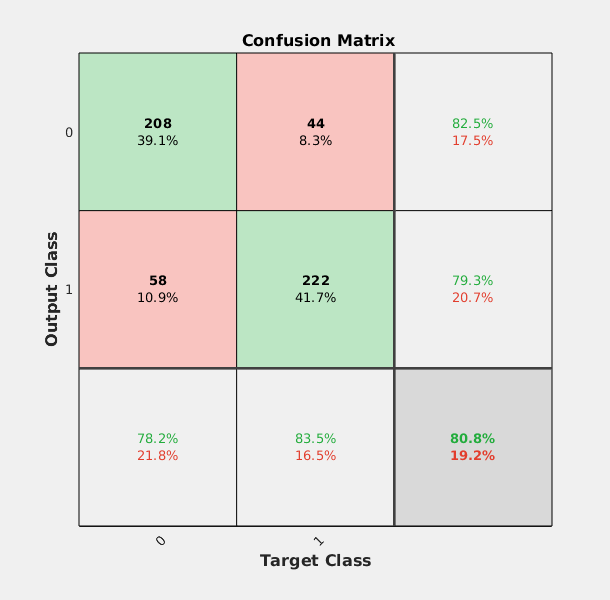

ans =    182   307   352   105   113   213   438   189    79    46    30    37   263    64   416   396   221   120   300   134   206   125    12   117   200    32   377    56   177   124   325    76    92   453    35   308     9   257   225   132   527   152   333   400   290    96    77   128   420   116


ans =    255   109   168   503   376   447   110   332    58   507   342   415    27   406    83   239   211   291   338   389   192   313   412    43   331   498   465   261   262     6   306   222   324   408   523   202   293   393   195   504   364   435   476   268   283   297   480   236    61    15


ans =      1    25    28    33    42    68    75    82    93    94    97   135   136   150   157   167   172   174   175   194   207   209   223   234   243   264   276   279   282   285   301   305   328   334   336   350   353   356   358   365   368   384   419   428   433   440   450   466   477   482


performance = 0.4685

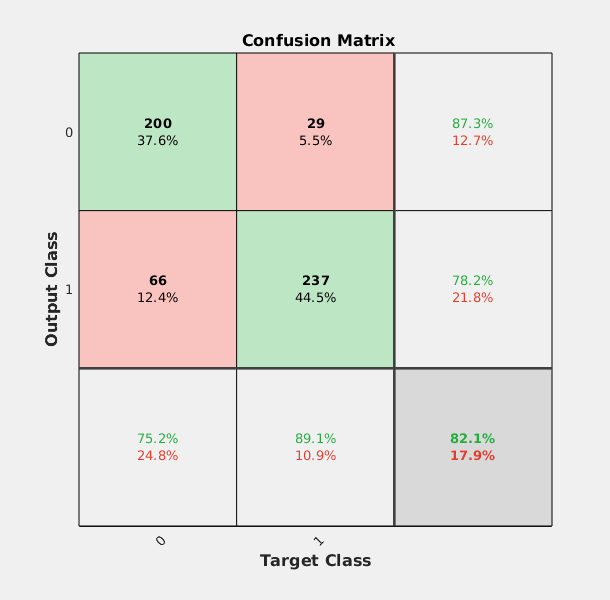

ans =    168   144   315     3   109   228   216   334   284   250   308   368   270   160    97   203   353   299   280   431   217   387   233   399    29    40   129   118   363   238   361    53   424   335    71   509     9   505   356   140   311   446     1   473   514    23   205   301   209   366


ans =    451    47   486   242   297   306   248   147   321   447    36   184   404   166   413    30   138    79    73   156   265   179   421   167   324   332   155   521   377   336   121   493   478   193   163   123   378   425   448   161   178   388   136   107    38   171   523   477   500   126


ans =     14    17    18    20    41    48    52    60    65    76    77   125   127   173   195   197   212   214   215   219   225   245   249   255   258   261   268   269   288   291   298   313   317   318   323   343   372   373   382   386   415   432   437   438   452   458   480   490   496   512


performance = 0.3249

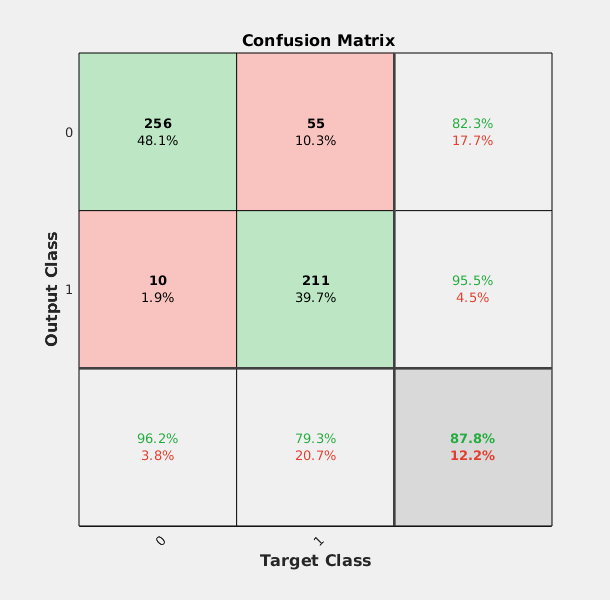

ans =     92   101   507   353   358   104   438    84   172    86   164   452   389   309    63   339   294   162   336   434   296   154   188   494   370    25   429   322   363   465   310   298    75   292   111   512   426   130   286   485   134   224    28   517   293    93   133    41   394   213


ans =     18   414    43   193   201    74   303   510   487   530   477   197   417   215   354    76    78   483    16   440   524   282   449   186   208   474   319   456   335    79   203    87   362   184   269   290    24   422   267   442   480    99   372   268     9   332   264   261   395   153


ans =      4    11    12    23    27    29    30    40    44    50    56    88    96   105   108   110   113   119   128   131   141   142   145   149   158   169   181   185   189   205   220   230   231   256   277   307   316   345   351   352   369   371   377   391   413   420   436   464   479   484


performance = 0.2983

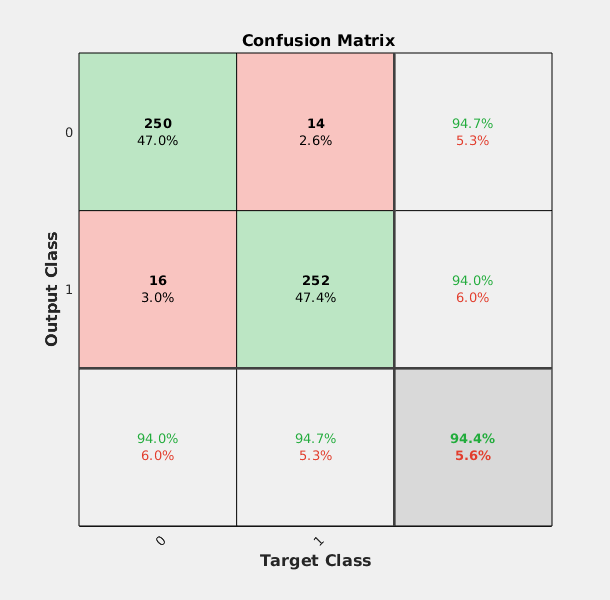

ans =    208     9   397   450     3   475   443   326   134   505   136   424   245    53   365   185   250   511   107   273     5   233     2   275   481   350   451   432   402   528    13   260   286   129   328    24   283   381    14   409   515   364   220   452   529   178   300   526   434   319


ans =    383   490   304    15   212    28   369   230   361   378   357   263   103    98   181   453    92   348   123   146   249   159   293    58   516    89   239   325   255   210   254   320   125   355    70   180   171   428    33    23   114   346   232   360   374    17    82   234   436   507


ans =      6     8    37    47    79   102   111   112   139   148   152   153   154   164   188   191   196   202   211   216   227   228   237   246   247   248   280   294   310   324   370   376   379   389   394   395   396   407   431   435   439   444   446   456   460   467   468   469   486   497


performance = 0.2960

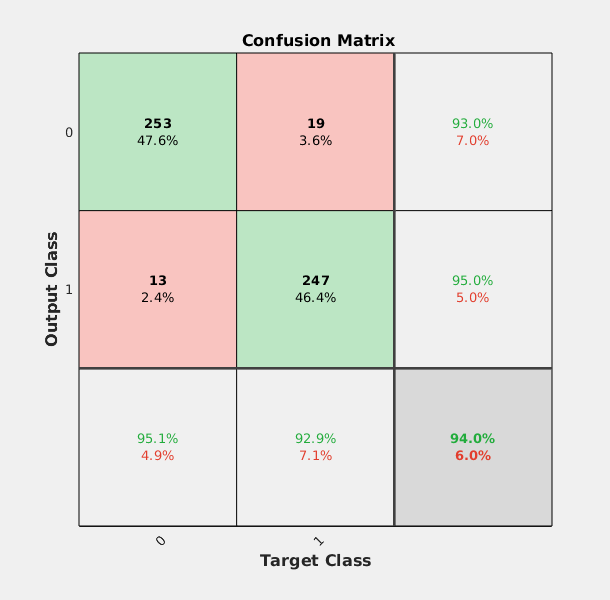

ans =    338   503   377   401    64   168   361   320   266   244   364   273   366    58   269   174   463   184   301   336   110   257    97    29   494   111   404    63   172   419   464    28   139   228   414   126   335   439   371   391   145   256   381   519   454   127   112   480   248   198


ans =    191   299   158   415   188   446   365   344   221   214   379   294   135   280   430   354   175    81   297   482   450   206   337   255   395   456   312   425   505   245   352   102   113    67   530   493   309   236   276   502   295   389   481    77   207   272   327   201   152   474


ans =      2     9    13    22    31    32    36    38    39    70    72    78    83   124   143   146   178   199   203   204   213   226   233   281   287   293   303   306   321   333   340   341   355   359   362   374   378   383   390   402   408   427   453   470   472   475   483   485   488   498


performance = 0.2960

ans =    300   203   467   329   453   237    43   367    29   154   102   161   407   343    90   118   307   378   191   136    71   119   150   413   446   232   372    35   108     3   262   303   435    95   464   418   270   188    24   164   114   437   344   216   285   481   230   366   497   320


ans =    116    97   202   456   359   293   496   251   135   165   236    74    63    51   509   336   190   153   395    42   238    53   103   441   382   379   482   181   178   272    92   340   199   392   485   302   396   151   354    47   225   375   149   279   129   381    23   428    67   163


ans =     21    34    54    61    69    73    80    81    84    89   100   109   123   130   133   137   159   160   166   171   182   183   192   206   221   241   260   271   278   304   308   311   335   338   339   388   399   406   411   412   414   421   430   442   443   454   457   493   494   495


performance = 0.2960

net.performFcn = 'crossentropy';
net.performParam.normalization = 'none';
for i=1:k
      testIdx = cvnn.test(i);               %# get indices of test instances
      trainIdx = cvnn.training(i) ;                  %# get indices training instances
      trInd = find(trainIdx);
      tstInd = find(testIdx);
      trInd_r = trInd(randperm(length(trInd)));
      ind1=(vertcat(trInd_r,tstInd))'; 
      Q1=length(trInd_r);
      Q2=length(tstInd);
     
      net.divideFcn = 'divideind'; 
      [net.divideParam.trainInd, net.divideParam.valInd, net.divideParam.testInd] = divideind(ind1,1:400,400:Q1,Q1+(1:Q2));
      net.divideParam.trainInd
      net.divideParam.valInd
      net.divideParam.testInd
      net.numinputs = 7;
      %net.inputConnect = [1 1 1 1 1 1 1;0 0 0 0 0 0 0];
      net.inputConnect = [1 1 1 1 1 1 1; 0 0 0 0 0 0 0; 0 0 0 0 0 0 0];
      
      %train the network
      [net,tr] = train(net,x,t);
      %plotperform(tr)
   
      y = net(x);
      y=cell2mat(y);
      e = gsubtract(t,y);
      performance = perform(net,t,y)
      tind = vec2ind(t);
      yind = vec2ind(y);
      percentErrors = sum(tind ~= yind)/numel(tind);
      figure, plotconfusion(t,y)
end